# Problem 1

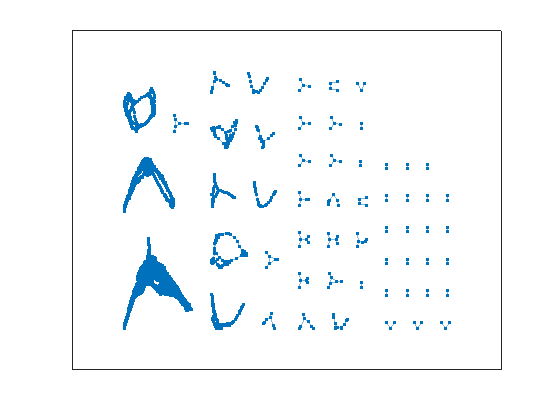

% Loading Data

data = load("usroads.mat");

G = graph(data.Problem.A);
plot(G)

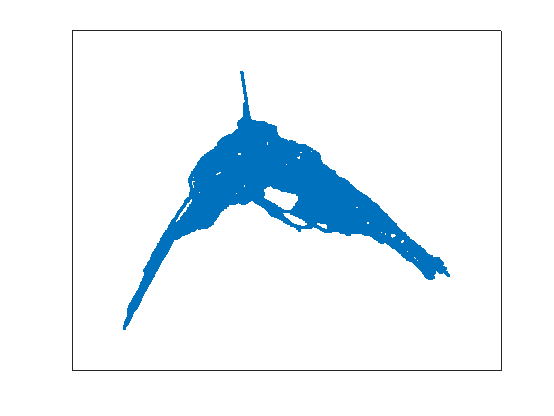

comps = conncomp(G);

SG = subgraph(G, comps==28);

plot(SG)

## Problem 1.1

A_SG = adjacency(SG);

%Adjacency matrix for Floritine families
A_SG2= [0 0 0 0 0 0 0 0 1 0 0 0 0 0 0;
0 0 0 0 0 1 1 0 1 0 0 0 0 0 0;
0 0 0 0 1 0 0 0 1 0 0 0 0 0 0;
0 0 0 0 0 0 1 0 0 0 1 0 0 1 0;
0 0 1 0 0 0 0 0 0 0 1 0 0 1 0;
0 1 0 0 0 0 0 0 0 0 0 0 0 0 0;
0 1 0 1 0 0 0 1 0 0 0 0 0 0 1;
0 0 0 0 0 0 1 0 0 0 0 0 0 0 0;
1 1 1 0 0 0 0 0 0 0 0 1 1 0 1;
0 0 0 0 0 0 0 0 0 0 0 0 1 0 0;
0 0 0 1 1 0 0 0 0 0 0 0 0 1 0;
0 0 0 0 0 0 0 0 1 0 0 0 0 1 1;
0 0 0 0 0 0 0 0 1 1 0 0 0 0 0;
0 0 0 1 1 0 0 0 0 0 1 1 0 0 0;
0 0 0 0 0 0 1 0 1 0 0 1 0 0 0];

A_SG = A_SG./sum(A_SG);

## Problem 1.2

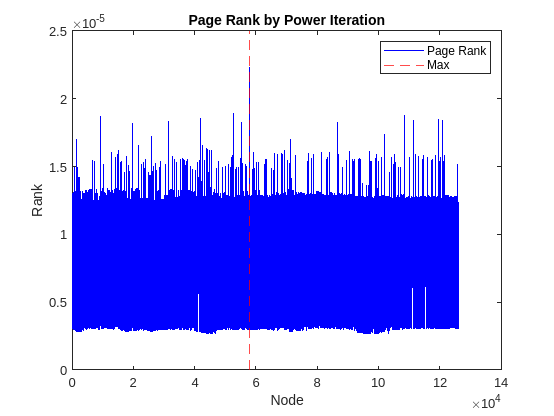

% Power Iteration
% Find the page rank of this network using power iteration.

n = length(A_SG);
iterations = 1000;

%Begin power iteration
x0=ones(n,1)/n;

for i = 1:iterations
    y0=A_SG*x0;
    x0=y0./sum(y0);
end

pr_pi = x0./sum(x0);

[v, I] = max(pr_pi);

plot(pr_pi, 'b')
hold on
xline(I, '--r')
hold off
title("Page Rank by Power Iteration");
xlabel("Node")
ylabel("Rank")
legend("Page Rank", "Max")

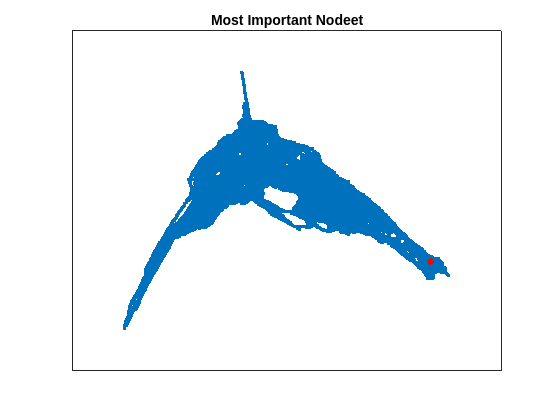

Og_g = plot(SG);
highlight(Og_g, I, 'NodeColor','red', 'MarkerSize',5)
title("Most Important Nodeet")

## Problem 1.3

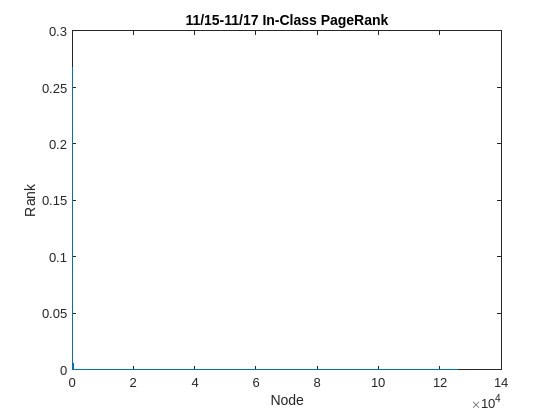

% Solve using the method discussed in class 11/15 11/17

alpha = 0.9;
k = 1000;
n = length(A_SG);

%Make a column vector of 1's normalized to n
v = eye(n, 1) / n;

%Do the zeroth iteration
partial = v;
v_sum = partial;

for i = 1:k
    partial = alpha*A_SG*partial;
    v_sum = v_sum + partial;
end

pr_iter = (1 - alpha)*v_sum;
pr_iter = pr_iter./sum(pr_iter);
plot(pr_iter)

title("11/15-11/17 In-Class PageRank");
xlabel("Node")
ylabel("Rank")

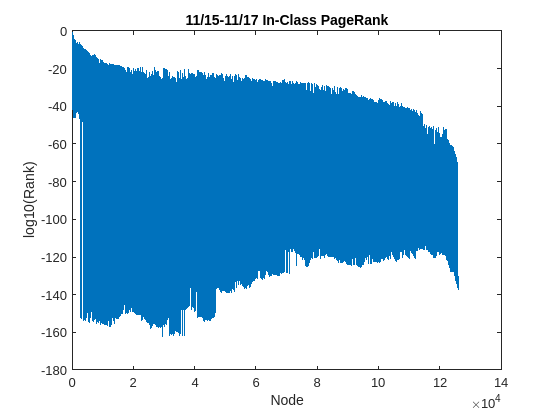

plot(log10(pr_iter))

title("11/15-11/17 In-Class PageRank");
xlabel("Node")
ylabel("log10(Rank)")

## Plot Comparisons with Power Iteration

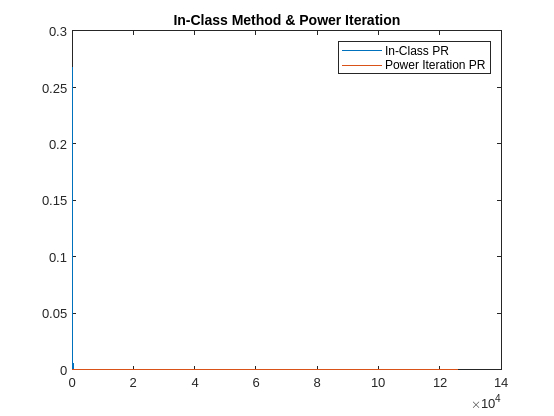

plot(pr_iter);
hold on
plot(pr_pi)
%plot(pr_eq)
%plot(pr_eig)
legend("In-Class PR", "Power Iteration PR");
title("In-Class Method & Power Iteration")
hold off

## Calculate Sensitivity

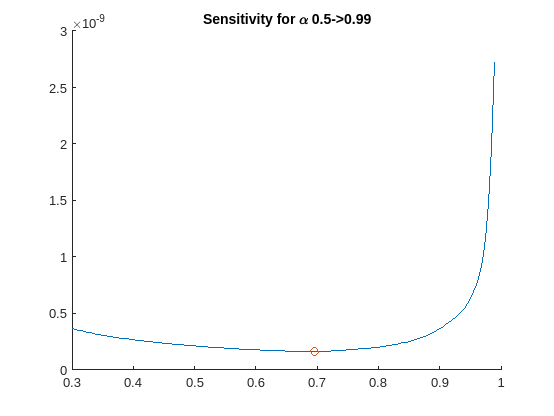

alphas = 0.3:0.005:0.99;
k = 150;
n = length(A_SG);

%Make a column vector of 1's normalized to n
v = eye(n, 1) / n;
count = 1;
s = zeros(n, count);

for alpha = alphas
    partial = A_SG * v;
    v_sum = alpha^(-1) * v + 2 * partial;
    
    for j = 2:k
        partial = alpha * A_SG * partial;
    
        v_sum = v_sum + (j + 1) * partial;
    end
    
    s(:, count) = v_sum - A_SG * v_sum;
    count = count + 1;
end

sense = mean(abs(s));
[lowest, idx] = min(sense);

figure()
hold on
plot(alphas, sense)
scatter(alphas(idx), lowest, 'o')
title("Sensitivity for \alpha 0.5->0.99")
hold off

## First 1000 Singular Values By RSVD

%Step 2
%Pull the size of the matrix
Asize = size(A_SG);
%m is x axis
m = Asize(1);
%n is y axis
n = Asize(2);
%Problem says find the first 1000 singular values using RSVD so r is 1100 oversample a bit
r = 1100;
%Create a random matrix that is n x r
X = randn(n,r);
%Multiply the matrices together to get AX
q = orth(A_SG*X);
%Do the QR factorization of AX to AX = QR
QTA = q'*A_SG

QTA =     0.0013    0.0013    0.0070    0.0016   -0.0019    0.0068   -0.0033   -0.0090    0.0024    0.0032    0.0080    0.0000   -0.0013   -0.0036    0.0021    0.0002    0.0014    0.0025   -0.0003   -0.0049    0.0068    0.0002   -0.0018   -0.0032    0.0080   -0.0096    0.0006    0.0006    0.0021    0.0046    0.0086    0.0020    0.0009   -0.0031   -0.0020    0.0106    0.0032   -0.0033    0.0059    0.0030   -0.0033    0.0021    0.0033   -0.0096   -0.0049    0.0001    0.0033   -0.0028   -0.0007   -0.0020
   -0.0003   -0.0003    0.0032   -0.0134    0.0012    0.0175    0.0023   -0.0014    0.0062    0.0038    0.0015    0.0048    0.0037   -0.0040   -0.0023   -0.0036    0.0008   -0.0033   -0.0100    0.0029    0.0175   -0.0057   -0.0101   -0.0116    0.0048    0.0019   -0.0012    0.0054    0.0024   -0.0074    0.0004   -0.0063   -0.0002   -0.0039    0.0082   -0.0058    0.0013    0.0031   -0.0024    0.0048   -0.0027    0.0019    0.0104    0.0060    0.0012   -0.0019    0.0015    0.0013    0.0005   

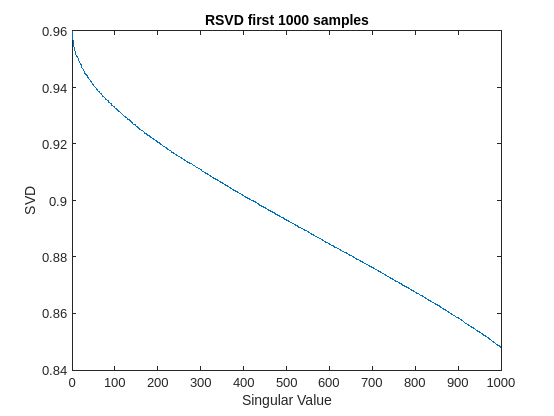

%Take the SVD of QTA
[uo,so,vot] = svd(QTA,"econ");
%Take the diagonal of the 
singvals = diag(so);
%figure(10)
plot(singvals(1:1000))
xlabel('Singular Value')
ylabel('SVD')
title('RSVD first 1000 samples')

## Minimal Route From 1000 to 1100:


src = 1000;
dest = 1100;

n = length(A_SG);

%Make a sparse vector
S = sparse(n,1);

%Index the sparse matrix using the endpoint
S(dest,1) = 1;

%Multiply the matrix by the sparse matrix
power = A_SG * S;

%Initialize distance
dist = 1;

while power(src, 1) == 0
    power = A_SG * power;
    dist=dist+1;
end

dist

dist = 140

## Split Graph with Fielder Method

L_SG = laplacian(SG);

[V_LSG, L_LSG, f_LSG] = eigs(L_SG,100,0);

Fiedler = V_LSG(:,2);

sum(Fiedler)

ans = 9.4670e-11


Positions = 1:height(SG.Nodes);

Cut = Fiedler > 0;

SG_1_nodes = Positions(Cut);
SG_2_nodes = Positions(~Cut);


## Plot the Cuts

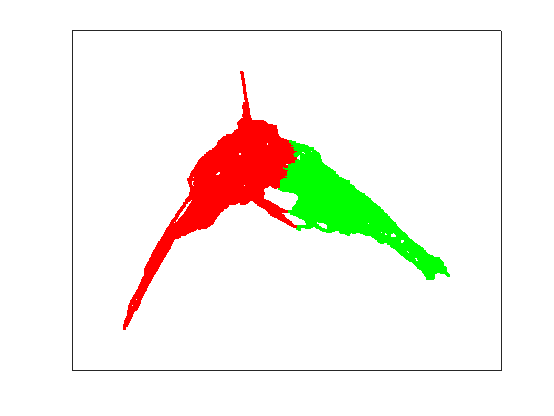

SG_plot = plot(SG);

%plot(SG)
highlight(SG_plot,SG_1_nodes,'NodeColor','r');
highlight(SG_plot,SG_2_nodes,'NodeColor','g');

## G49.mat

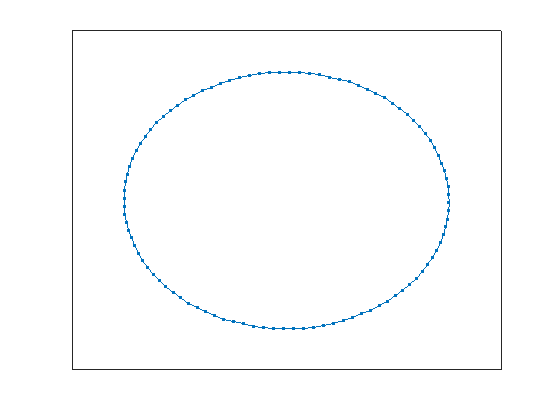

load('G49.mat')

Graph_G49 = graph(Problem.A);
plot(Graph_G49)

## Calculate the Page Rank with Power Iteration

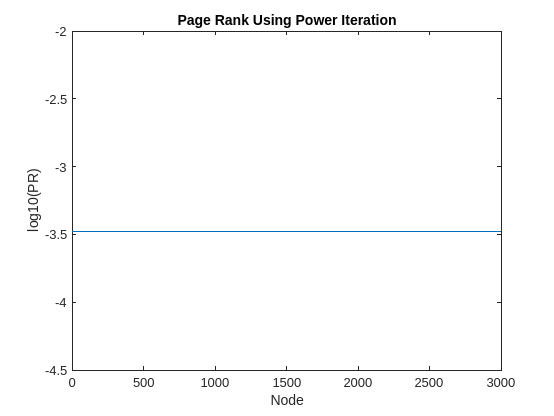

% Power Iteration
% Find the page rank of this network using power iteration.

A = Problem.A./sum(Problem.A);

n = length(A);
iterations = 1000;

%Begin power iteration
x0=ones(n,1)/n;

for i = 1:iterations
    y0=A*x0;
    x0=y0./sum(y0);
end

pr_pi = x0./sum(x0);
plot(log10(pr_pi));
ylabel('log10(PR)')
xlabel('Node')
title('Page Rank Using Power Iteration')

9

ans = 9

## Calculate PageRank

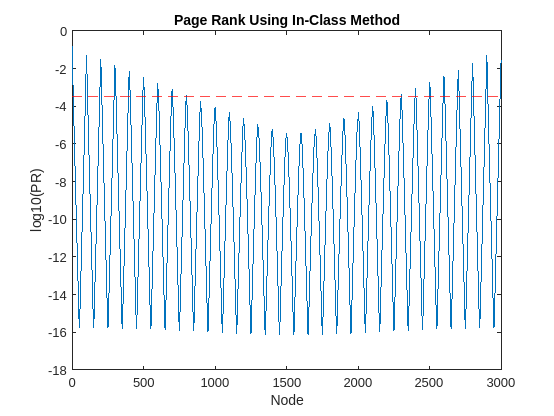

% Solve using the method discussed in class 11/15 11/17

alpha = 0.9;
k = 1000;
n = length(A);

%Make a column vector of 1's normalized to n
v = eye(n, 1) / n;

%Do the zeroth iteration
partial = v;
v_sum = partial;

for i = 1:k
    partial = alpha*A*partial;
    v_sum = v_sum + partial;
end

pr_iter = (1 - alpha)*v_sum;
pr_iter = pr_iter./sum(pr_iter);
plot(log10(pr_iter))
hold on
yline(-3.5, '--r')
hold off
ylabel('log10(PR)')
xlabel('Node')
title('Page Rank Using In-Class Method')

## Calculate Sensitivity

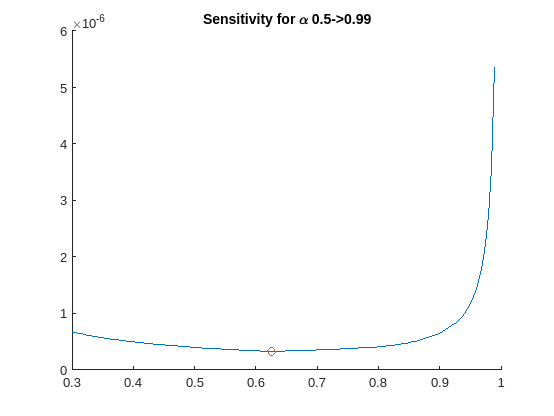

alphas = 0.3:0.005:0.99;
k = 150;
n = length(A);

%Make a column vector of 1's normalized to n
v = eye(n, 1) / n;
count = 1;
s = zeros(n, count);

for alpha = alphas
    partial = A * v;
    v_sum = alpha^(-1) * v + 2 * partial;
    
    for j = 2:k
        partial = alpha * A * partial;
    
        v_sum = v_sum + (j + 1) * partial;
    end
    
    s(:, count) = v_sum - A * v_sum;
    count = count + 1;
end

sense = mean(abs(s));
[lowest, idx] = min(sense);

figure()
hold on
plot(alphas, sense)
scatter(alphas(idx), lowest, 'o')
title("Sensitivity for \alpha 0.5->0.99")
hold off

## First 1000 Singular Values

%Step 2distendpoint
%Pull the size of the %Find the minimum of S that isn't ~zero

[M, I] = min(s(abs(s) > 1e-15));

Asize = size(A);
%m is x axis
m = Asize(1);
%n is y axis
n = Asize(2);
%Problem says find the first 1000 singular values using RSVD so r is 1100 oversample a bit
r = 1100;
%Create a random matrix that is n x r
X = randn(n,r);
%Multiply the matrices together to get AX
q = orth(A*X);
%Do the QR factorization of AX to AX = QR
QTA = q'*A

QTA =    -0.0130    0.0020    0.0063    0.0171   -0.0048    0.0134   -0.0033    0.0092    0.0057    0.0021   -0.0189    0.0024   -0.0080    0.0162    0.0043    0.0191    0.0061    0.0081   -0.0095    0.0213   -0.0033    0.0098   -0.0067   -0.0047   -0.0088   -0.0046   -0.0024    0.0039   -0.0086    0.0063   -0.0250    0.0028   -0.0175   -0.0027    0.0196   -0.0160    0.0348   -0.0296    0.0297   -0.0198    0.0176   -0.0251    0.0040   -0.0188   -0.0013   -0.0090   -0.0130    0.0020   -0.0129   -0.0007
    0.0048   -0.0086   -0.0046    0.0005   -0.0197    0.0049   -0.0364    0.0106   -0.0128    0.0054    0.0156    0.0023    0.0261   -0.0103    0.0163   -0.0244    0.0109   -0.0198    0.0136    0.0098    0.0146    0.0145   -0.0015    0.0099   -0.0237    0.0153    0.0009   -0.0058    0.0048    0.0003   -0.0010    0.0094    0.0049    0.0096    0.0082    0.0034    0.0110   -0.0185   -0.0091   -0.0169   -0.0150   -0.0036   -0.0058   -0.0107    0.0048   -0.0207   -0.0021   -0.0045   -0.0273   

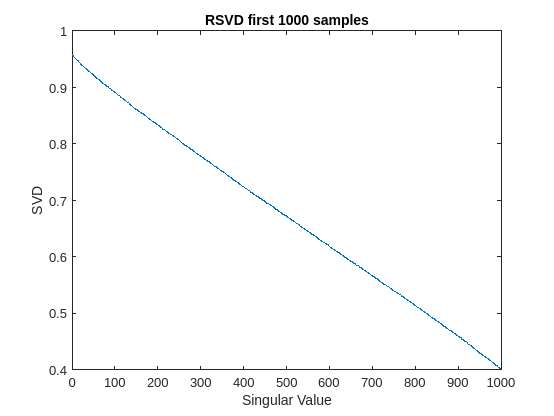

%Take the SVD of QTA
[uo,so,vot] = svd(QTA,"econ");
%Take the diagonal of the 
singvals = diag(so);
%figure(10)
plot(singvals(1:1000))
xlabel('Singular Value')
ylabel('SVD')
title('RSVD first 1000 samples')

## Path from 1000 to 1100


src = 1000;
dest = 1100;
n = length(A);

%Make a sparse vector
S = sparse(n,1);

%Index the sparse matrix using the endpoint
S(dest,1) = 1;

%Multiply the matrix by the sparse matrix
PA = A * S;

%Initialize distance
dist = 1;

while PA(src, 1) == 0
    PA = A * PA;
    dist=dist+1;
end

dist

dist = 1

## Cut Graph

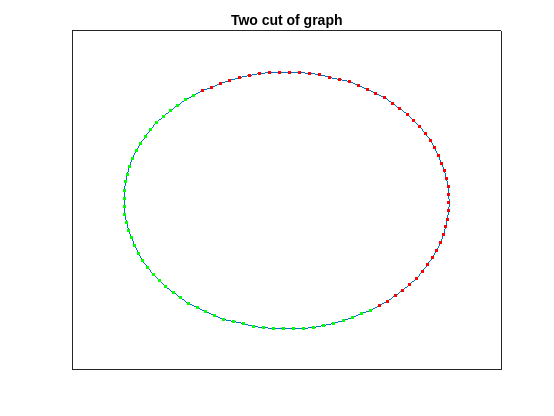


L = laplacian(Graph_G49);
[D, S] = eigs(L, 3000);

Positions = 1:height(Graph_G49.Nodes);

s = diag(S);

%Find the minimum of S that isn't ~zero
[M, I] = min(s(abs(s) > 1e-15));

Cut = D(:,I) > 0;

H1_nodes = Positions(Cut);
H2_nodes = Positions(~Cut);

H1 = rmnode(Graph_G49, H1_nodes);
H2 = rmnode(Graph_G49, H2_nodes);

G_2plot = plot(Graph_G49);
highlight(G_2plot,H1_nodes,'NodeColor','g');
highlight(G_2plot,H2_nodes,'NodeColor','r')
title("Two cut of graph")

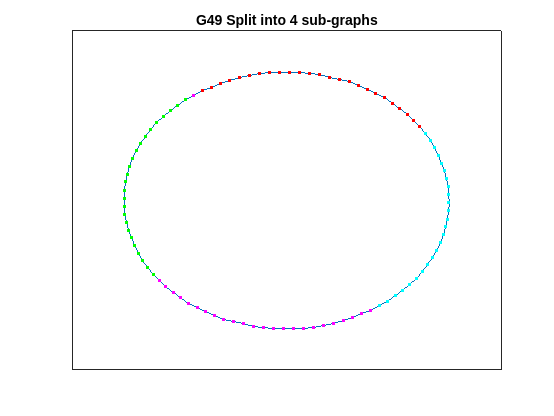


G_plot = plot(Graph_G49);
highlight(G_plot,H1_nodes,'NodeColor','g');
highlight(G_plot,H2_nodes,'NodeColor','r')

% Split the first half in two
L1 = laplacian(H1);
n1 = height(H1.Nodes);
[D1, S1] = eigs(L1, n1);

Pn1 = 1:n1;

s1 = diag(S1);

%Find the minimum of S that isn't ~zero
[M1, I1] = min(s1(abs(s1) > 1e-10));

Cut1 = D1(:,I1) > 0;

H11 = rmnode(H1, Pn1(~Cut1));
H12 = rmnode(H1, Pn1(Cut1));

H11_nodes = H1_nodes(Cut1);
H12_nodes = H1_nodes(~Cut1);

highlight(G_plot,H11_nodes,'NodeColor','magenta');

% Split the second half in two
L2 = laplacian(H2);
n2 = height(H2.Nodes);
[D2, S2] = eigs(L2, n2);

Pn2 = 1:n2;

s2 = diag(S2);

%Find the minimum of S that isn't ~zero
[M2, I2] = min(s2(abs(s2) > 1e-10));

Cut2 = D1(:,I2) > 0;

H21 = rmnode(H2, Pn2(~Cut2));
H22 = rmnode(H2, Pn2(Cut2));

H21_nodes = H2_nodes(Cut2);
H22_nodes = H2_nodes(~Cut2);

highlight(G_plot,H21_nodes,'NodeColor','cyan');
title("G49 Split into 4 sub-graphs")

### Find the Dirichlet PageRank

An_G49 = full(Problem.A ./ sum(Problem.A))

An_G49 =          0    0.2500         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.2500         0    0.2500         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

n = length(H22_nodes);
alpha = 0.5;

A21 = An_G49(H22_nodes,H22_nodes);
A22 = An_G49(H21_nodes,H21_nodes);

Adir = [eye(750,750),zeros(750,750);
        A22,A21];

Adir = Adir./sum(Adir);

xdir=inv(eye(n) - alpha*A22) * ((1-alpha)*ones(n,1)+alpha*A21*ones(n,1)/n)

xdir =     0.8293
    0.9718
    0.9963
    1.0005
    1.0012
    1.0013
    1.0013
    1.0013
    1.0013
    1.0013


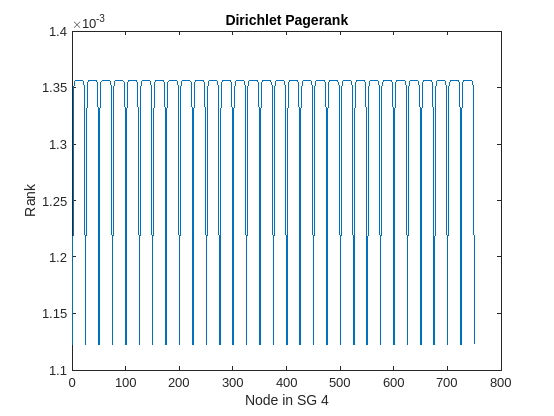

xdir = xdir ./ sum(xdir);
plot(xdir)
title("Dirichlet Pagerank")
xlabel("Node in SG 4")
ylabel("Rank")

## Centrality of Nodes

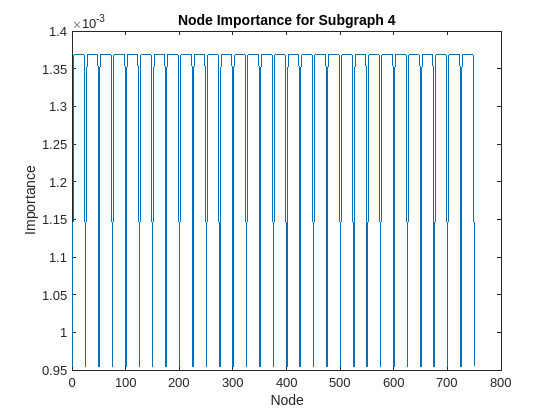


A_small = adjacency(H22);
Central = expm(A_small);
central_nodes = diag(Central);
central_nodes = central_nodes ./ sum(central_nodes);

plot(central_nodes)
xlabel("Node")
ylabel("Importance")
title("Node Importance for Subgraph 4")

## Comparing Centralities

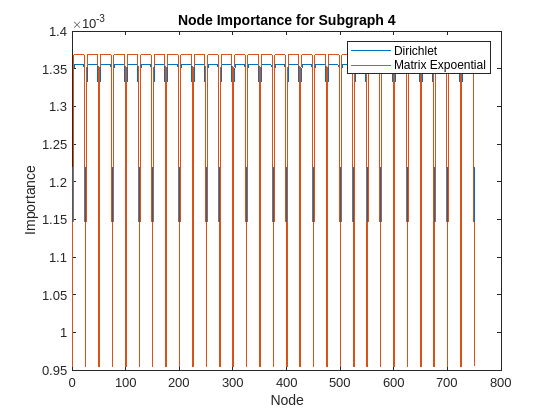

plot(xdir)
hold on
plot(central_nodes)
hold off
xlabel("Node")
ylabel("Importance")
title("Node Importance for Subgraph 4")
legend(["Dirichlet", "Matrix Expoential"])